# Magnetorquer Characterization

For design of control systems, it is necessary to produce accurate models of how our magnetorquers will behave. This document will include the relevant mathematics and various parameters needed to fully define the model that will be generated in this script. Please note the following:

- The main equations used in this document are the final equations after construction from base principles. Refer to the following for the complete derivations of these equations: [http://www.m-hikari.com/ces/ces2010/ces5-8-2010/fakhariCES5-8-2010.pdf](http://www.m-hikari.com/ces/ces2010/ces5-8-2010/fakhariCES5-8-2010.pdf)

- Other parameters used within this modelling was calculated from the magnetorquer design team and is available at the following link: [https://www.notion.so/uworbital/Magnetorquer-92b8c5e754ac41cc9806cb4a7eefe373](https://www.notion.so/uworbital/Magnetorquer-92b8c5e754ac41cc9806cb4a7eefe373)

## Magnetic Dipole

The following equation allows calculating the magnetic dipole generated by the current passing through the windings of the magnetorquer.

- Includes moments generated by the windings and the ferromagnetic core

- All parameters of this equation are based on a combination of material properties and parameters of the cyclindrical geometry

- Only input signal required is current running through the windings

- Based on a linearization of the hysteresis for the ferromagnetic core and is therefore valid only in the linear region

For a cyclindrical magnetorquer the total magnetic dipole of the magnetorquer is the following:

$M_\text{tot}=\pi r^2 N i \left( 1 + \frac{\mu_r - 1}{1 + (\mu_r - 1) N_d)} \right)$, $N_d = \frac{4(\ln(l/r) - 1)}{(l/r)^2-4\ln(l/r)}$


$$N = \frac{l_\text{wire}}{2\pi r} \longrightarrow M_\text{tot}=\left(\frac{l_\text{wire}r}{2}\right)i\times\left(1 + \frac{\mu_r - 1}{1 + (\mu_r - 1)N_d}\right)$$


- $\mu_r$ is core relative permeability

- $l$ is length of core

- $r$ is radius of core

- $N_d$ is demagnetization factor

- $i$ is current in the windings

- $N$ is number of windings

- $l_\text{wire}$ is the total length of wire making up the windings

% Properties of the ferromagnetic core
core_length = 63e-3; % core length [m]
core_rad = 12.7e-3 / 2; % core radius [m]
core_rel_perm = 50; % core relative permeability

% Characteristics of windings
wind_max_volt = 5; % max voltage provided to coil [V]
wind_max_pow = 0.8; % max power provided to coil [W]
wind_min_resis = wind_max_volt^2 / wind_max_pow % resistance of windings [ohm]

wind_min_resis = 31.2500

wind_max_cur = wind_max_volt / wind_min_resis % current carried by coil [A]

wind_max_cur = 0.1600

% Characteristics of the wire of the windings
wire_rho = 0.21292; % resitivity of 28 AWG wire [ohm/m]
wire_len = wind_min_resis / wire_rho % length of wire [m]

wire_len = 146.7687

% Calculates the demagnetization factor and the max dipole generated when
% the current is at the maximum value provided to the windings
demag_fact = 4 * (log(core_length/core_rad)-1)/((core_length/core_rad)^2-4*log(core_length/core_rad)) % unitless

demag_fact = 0.0580

max_dipole = (wire_len * core_rad) / 2 * wind_max_cur * ...
    (1 + (core_rel_perm - 1) / (1 + (core_rel_perm - 1) * demag_fact)) % max dipole from magnetorquers[Am^2]

max_dipole = 1.0252

The maximum dipole calculated in this case is the same as the calculated value in the spreadsheet which used a formulation of the dipole based on current and resitivity. This calculation is preferable when compared with the voltage formulation as this can be used with a transfer function to dipole based on the current present in a circuit.


$$M_\text{tot}=\left(\frac{l_\text{wire}r}{2}\right)i\times\left(1 + \frac{\mu_r - 1}{1 + (\mu_r - 1)N_d}\right) \longrightarrow \frac{M(s)}{I(s)} = \left(\frac{l_\text{wire}r}{2}\right)\left(1 + \frac{\mu_r - 1}{1 + (\mu_r - 1)N_d}\right)$$


% Note that the transfer function below is functionally just a gain
dipole_cur_tf = (wire_len * core_rad) / 2 * (1 + (core_rel_perm - 1) / (1 + (core_rel_perm - 1) * demag_fact))

dipole_cur_tf = 6.4074

## LR Function Modelling

Given the nature of the windings being similar to an inductor, it is necessary to model the function as an LR circuit. The following will calculate the inductance of the coil and then will model a transfer function from system input voltage to generated current.


$$L = \frac{\Delta \Phi_B}{\Delta i} = \frac{\mu_0\pi r^2 N^2}{l\left(\frac{1}{\mu_r}+ N_d\right)}$$



$$N = \frac{l_\text{wire}}{2\pi r} \longrightarrow L = \frac{\mu_0 l_\text{wire}^2}{4\pi l \left( \frac{1}{\mu_r} + N_d \right)}$$


perm_free_space = 1.25663706e-6; % permeability of free space [kg*s^-2*A^-2]
wind_induct = perm_free_space * wire_len^2 / (4*pi*core_length*(1/core_rel_perm + demag_fact)) % inductance of the windings [H]

wind_induct = 0.4382


$$v_0 = iR + L\frac{di}{dt} \longrightarrow V_0(s) = I(s)R + LI(s)s \longrightarrow \frac{I(s)}{V_0(s)} = \frac{1}{Ls + R}$$


% Calculates the transfer function from the input voltage to the current
% present within the system (expected to decay when input removed)
s = tf('s');
cur_volt_tf = 1 / (wind_induct * s + wind_min_resis)

cur_volt_tf =
 
         1
  ----------------
  0.4382 s + 31.25
 
Continuous-time transfer function.



% bode(cur_volt_tf);
% pzmap(cur_volt_tf);

% impulse(cur_volt_tf);
% step(cur_volt_tf);

## Complete Transfer Function

Given that the dipole is a transfer function (gain) from the current present within the system, a transfer function can be constructed from the input voltage signal to the output dipole signal.

% Constructs the overall transfer function from the input voltage to the
% output dipole moment of the magnetorquer
dipole_volt_tf = cur_volt_tf * dipole_cur_tf

dipole_volt_tf =
 
       6.407
  ----------------
  0.4382 s + 31.25
 
Continuous-time transfer function.



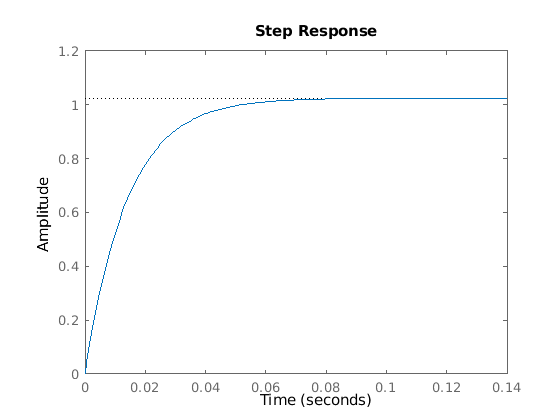

% Feeds in the maximum voltage to the system and the steady state response
% will be the maximum dipole as calculated previously
step(wind_max_volt * dipole_volt_tf);

% Shows decay of dipole when input voltage is removed
% impulse(dipole_volt_tf);

% For convenience of control systems development, an additional gain will
% be provided to the system that will allow input of a commanded dipole
% which will have an output of the current dipole of the system
dipole_com_dipole_tf = (wind_max_volt / max_dipole) * dipole_volt_tf

dipole_com_dipole_tf =
 
       31.25
  ----------------
  0.4382 s + 31.25
 
Continuous-time transfer function.



% Should be able to set a desired dipole which will will become the
% steady-state response of the system
step(max_dipole * dipole_com_dipole_tf);

% Provides the state-space representation
ss(dipole_com_dipole_tf)

ans =
 
  A = 
           x1
   x1  -71.31
 
  B = 
       u1
   x1   8
 
  C = 
          x1
   y1  8.914
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.

